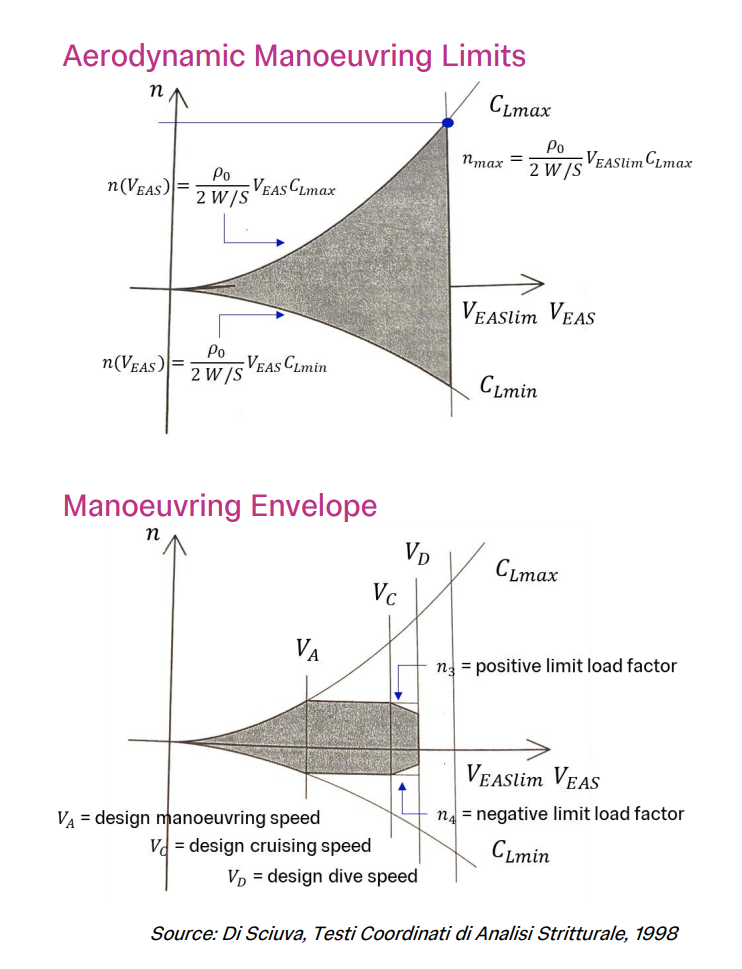

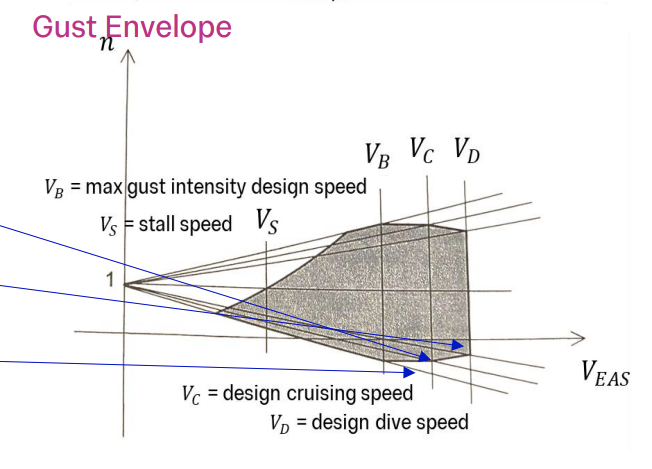

## **V-n diagram**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0. Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea Level Condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Aircraft Design Parameters**

W0 = 4.2990e+05;                   % MTOW (kg)
W0 = W0 * g;                       % MTOW (N)
WC = 0.9554 .* W0;                 % Cruise weight when starting 1st cruise (N)
% WC = 0.5806 .* W0;               % Cruise weight when ending 1st cruise (N)

CLmax = 1.4413                     % Maximum lift coefficient at clean configuration
CLmaxL = 2.8734                    % Maximum lift coefficient at landing configuration

CD0 = 0.0188;                      % Drag coefficient at zero lift

Sref = 548.7;                      % Reference wing area (m^2)

Sweep = 25.5257;                   % Wing 1/4 chord sweep (degree)
Sweep = deg2rad(Sweep);            % Wing 1/4 chord sweep (rad)

### **1. Design Airspeeds**

The selected design airspeeds are equivalent airspeeds (EAS)

**1.1 Design Cruising Speed, **$V_C$

CS 25.335 (a) (p.212)

Airframe Structural Design (p.76)

MC = 0.83;                          % Design cruising speed (Mach)

Calt = 28000;                      % Design cruising altitude (ft)
Calt = convlength(Calt, 'ft','m')  % Design cruising altitude (m)

[TC, aC, PC, rhoC] = atmosisa(Calt);


$$V_{\textrm{EAS}} =\sqrt{\frac{\rho }{\rho_0 }}V_{\textrm{TAS}}$$


VC_TAS = aC .* MC                  % Design cruising true airspeed (m/s)
VC = sqrt(rhoC ./ rho0) .* VC_TAS  % Design cruising equivalent airspeed (m/s)

**1.2 Design Dive Speed, **$V_D$

CS 25.335 (b) (p.212)

% VD = sqrt(2 .* WC ./ (rho0 .* CD0 .*Sref))

$V_D$ must be selected so that $\frac{V_C }{M_C }$ is not greater than $0\ldotp 8\frac{V_D }{M_D }$

VD = VC ./ 0.8                     % Design dive equivalent airspeed (m/s)

### **2. Aerodynamic Manoeuvring Limits**

Vspace = linspace(0, VD, 1000)

**2.1 Flaps Up (Clean Configuration)**


$$n=\frac{L}{W}=\frac{1}{W}\left(\frac{1}{2}\rho V^2 S_{\textrm{ref}} C_{L_{\max } } \right)$$


L = 0.5 .* rho0 .* (Vspace .^ 2) .* Sref .* CLmax;

n_upperline = L ./ WC;

**2.1 Flaps Down (Landing Configuration)**

L_L = 0.5 .* rho0 .* (Vspace .^ 2) .* Sref .* CLmaxL;

n_upperline_L = L_L ./ WC;

**2.3 Minimum Lift Coefficient**

SC20714 ($N_{\mathrm{crit}} =9$, $\textrm{Re}=1000000$)

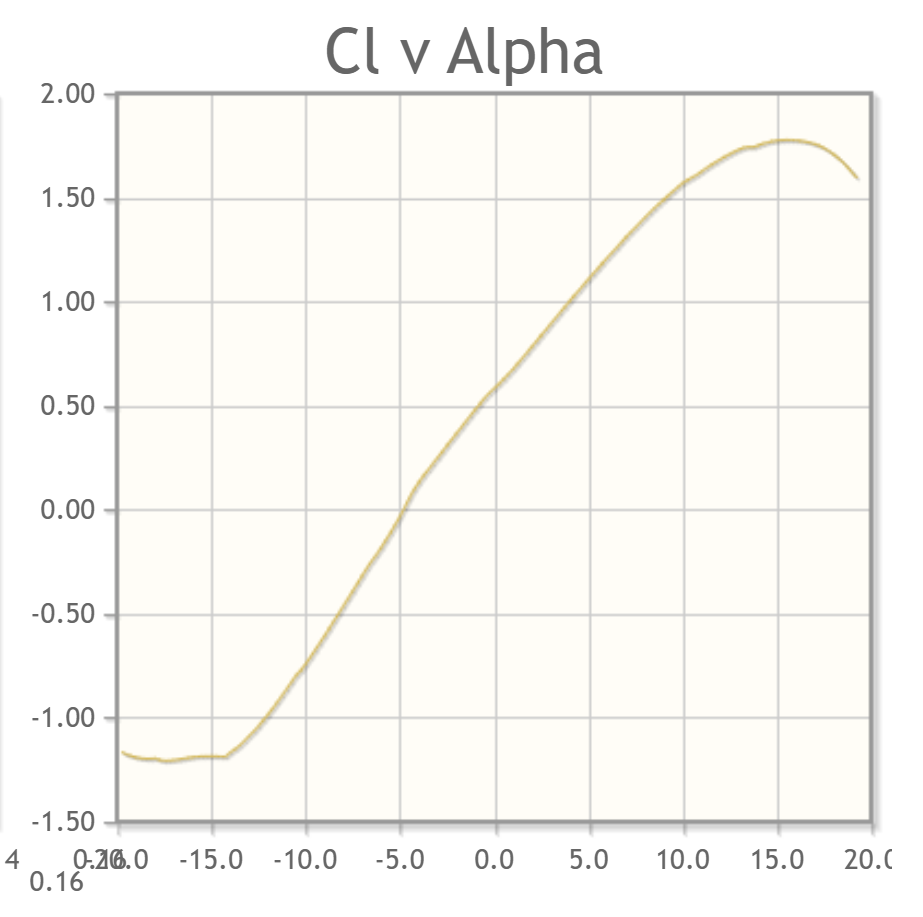

Clmin = -1.2;

Approximate 3D effects


$$C_{L_{\min } } =0\ldotp 9C_{l_{\min } } \cdot \cos \left(\Lambda_{0\ldotp 25c} \right)$$


CLmin = 0.9 .* Clmin .* cos(Sweep) 

L_min = 0.5 .* rho0 .* Vspace .^ 2 .* Sref .* CLmin;

n_lowerline = L_min ./ WC;

**2.4 Maximum Load Factor**

% nmax = CLmax ./ CD0

**2.5 Positive Limit Manoeuvring Load Factor**

CS 25.337 (p.217)

$n\ge 2\ldotp 5$ and $n\ge 2\ldotp 1+\left(\frac{24000}{W+10000}\right)$

nmax = 2.1 + 24000 ./ (convmass(W0 ./ g, "kg", "lbm") + 10000)

if nmax >= 2.5
else
    nmax = 2.5
end

% Compute n4
n4 = zeros(size(Vspace));
for i = 1 : length(Vspace)
    if Vspace(i) <= VC
        n4(i) = -nmax; % n4 = -n3 from VEAS = 0 to VC
    elseif Vspace(i) > VC && Vspace(i) <= VD
        % n4 decreases linearly from -n3 at VC to 0 at VD
        n4(i) = -nmax * (VD - Vspace(i)) / (VD - VC);
    else
        n4(i) = 0; % Beyond VD, n4 is zero
    end
end

**2.5 Negative Limit Manoeuvring Load Factor**

nmin = -1;

**2.6 Design Manoeuvring Speed, **$V_A$

CS 25.335 (b) (p.212)


$$W_C =L=\frac{1}{2}\rho_0 V_{\textrm{S1}}^2 S_{\textrm{ref}}$$


VS1 = sqrt(2 .* WC ./ (Sref .* rho0 .* CLmax)) % Stalling speed with wing-flaps retracted (m/s)
% VS1_min = sqrt(2 .* W0 ./ (Sref .* rho0 .* abs(CLmin))) % Stalling speed with wing-flaps retracted (m/s)


$$V_A \ge V_{\textrm{S1}} \sqrt{n_{\max } }$$


VA = VS1 * sqrt(nmax);

**2.6 Design Wing-flap Speed, **$V_F$

CS 25.335 (e) (p.214)


$$V_F \ge {1\ldotp 6V}_{\textrm{S1}}$$


VF = 1.6 * VS1

**2.8 Plot Manoeuver envelope**

CS 25.333 (b) (p.211)

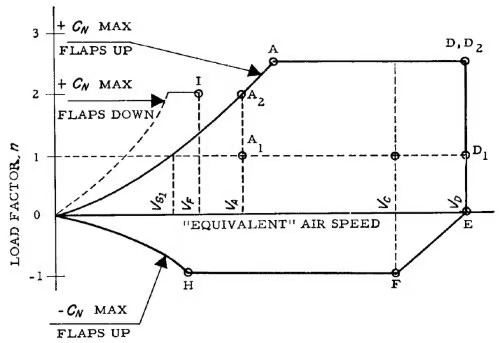

Find intersection point

% First segment of upper curve

Vspace1 = linspace(0, VS1, 1000);

L1 = 0.5 .* rho0 .* (Vspace1 .^ 2) .* Sref .* CLmax;

n_upper1 = L1 ./ WC;

% Second segment of upper curve

Vspace2 = linspace(VS1, VD, 1000);

L2 = 0.5 .* rho0 .* (Vspace2 .^ 2) .* Sref .* CLmax;

n_upper2 = L2 ./ WC;

for i = 1 : length(n_upper2)
    if n_upper2(i) <= nmax
    else
        n_upper2(i) = nmax;
    end
end

% Thrid segment of upper curve

Vspace2 = [Vspace2 VD];

n_upper2 = [n_upper2 0];

% first segment of lower curve

% I am not sure which V_s should be used here, see slide page 21

Vspace3 = linspace(0, VS1, 1000);

L1_min = 0.5 .* rho0 .* Vspace3 .^ 2 .* Sref .* CLmin;

n_lower1 = L1_min ./ WC;

% second segment of lower curve

Vspace4 = linspace(VS1, VC, 1000);

L2_min = 0.5 .* rho0 .* Vspace4 .^ 2 .* Sref .* CLmin;

n_lower2 = L2_min ./ WC;

for i = 1 : length(n_lower2)
    if n_lower2(i) >= nmin
    else
        n_lower2(i) = nmin;
    end
end

% thrid segment of lower curve

Vspace5 = linspace(VC, VD, 1000);

n_lower3 = (1 ./ (VD - VC)) .* Vspace5 + (VD ./ (VC - VD));

% First segment of upper curve with landing configuration

% I am not sure what n should be used here, see graph above

Plotting

Using the book

dCLdalpha = 4.4359;
cbar = 9.9496;
mu = 2*(WC/Sref)/(rhoC*g*cbar*dCLdalpha);
K = 0.88*mu/(5.3 + mu);
Ude = [20,15.2,7.6]
U = K * Ude


Using CS25

Zmo = 45000;
WML = 3795587.1; %maximum landing weight in N
WF = 1928646; %fuel weight in N
Fgz = 1 - Zmo/250000;
R1 = WML/W0;
R2 = (W0-WF)/W0;
Fgm = sqrt(R2*tan(pi*R1/4));
Fg = 0.5*(Fgz + Fgm)
Uref = [17.07; 13.41; 7.92]
Alt = [0; 4572; 15240]
H = linspace(9,107,3);
Uds = Uref.*Fg.*(H./350).^(1/6);
u = Uds;


figure(1)
clf;

% Plotting various lines
plot(Vspace1, n_upper1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
hold on;
plot(Vspace2, n_upper2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace3, n_lower1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace4, n_lower2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace5, n_lower3, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace, n_upperline_L, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25);
labels = ["VB", "VC", "VD"];

% Adding gust load factor lines
for i = 1:size(U,2)
    % Compute gust load factors
    ngust_1 = 1 + rhoC * U(i) .* Vspace .* dCLdalpha / (2 * WC / Sref);
    ngust_2 = 1 - rhoC * U(i) .* Vspace .* dCLdalpha / (2 * WC / Sref);
    
    % Plot gust lines
    plot(Vspace, ngust_1, 'b-.', 'LineWidth', 1.5);
    hold on;
    plot(Vspace, ngust_2, 'b-.', 'LineWidth', 1.5);
    hold on;
    
    % Add labels at the end of each line with LaTeX font
    text(Vspace(end)+5, ngust_1(end), ['$' char(labels(i)) '$'], ...
        'Interpreter', 'latex', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 10);
    text(Vspace(end)+5, ngust_2(end), ['-$' char(labels(i)) '$'], ...
        'Interpreter', 'latex', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 10);
end



% Vertical lines
xline(VD, '--', 'LineWidth', 2);
xline(VC, '--', 'LineWidth', 2);
xline(VA, '--', 'LineWidth', 2);
xline(VS1, '--', 'LineWidth', 2);

% Adding labels to vertical lines with LaTeX font
text(VD+5, 0.2, '$V_D$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');
text(VC+5, 0.2, '$V_C$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');
text(VA+5, 0.2, '$V_A$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');
text(VS1+5, 0.2, '$V_{S1}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');

% Axis labels with LaTeX font
xlabel('$V_{\mathrm{EAS}} \, (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('Airplane load factor $(n)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 9.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 VD * 1.2]);
ylim([-1.5 3]);
grid on;
% Desired plots for the legend
x = 1:10;
h1 = plot(-x, rand(1, 10), 'b-', 'LineWidth', 1.5); % Solid line
h2 = plot(-x, rand(1, 10), 'b-.', 'LineWidth', 1.5); % Dash-dot line
h3 = plot(-x, rand(1, 10), 'b--', 'LineWidth', 1.5); % Dashed line

% Add legend for the selected plots
legend([h1, h2, h3], {'Limit Combined Envelope', 'Limit Gust Envelope', 'Limit Manoeuvre Envelope'}, ...
    'Location', 'best', 'Interpreter', 'latex');

% Set figure size
set(gcf, 'Position', [0 0 1000 1000]);


### **3. Gust and Turbulences Loads**

**2.7 Alleviation**

CS 25.341 (a) (p.219)

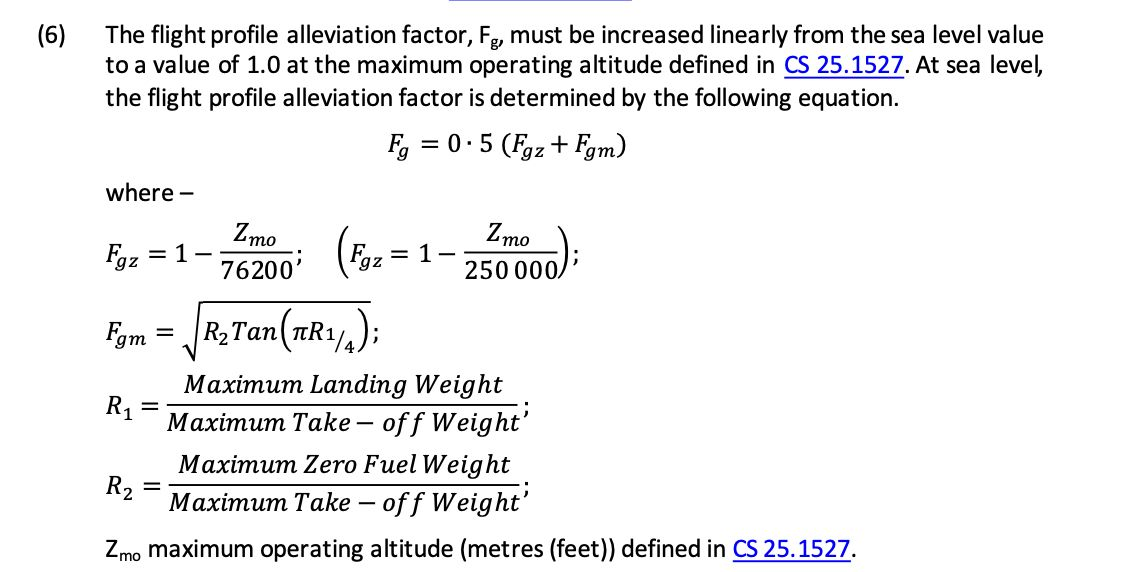

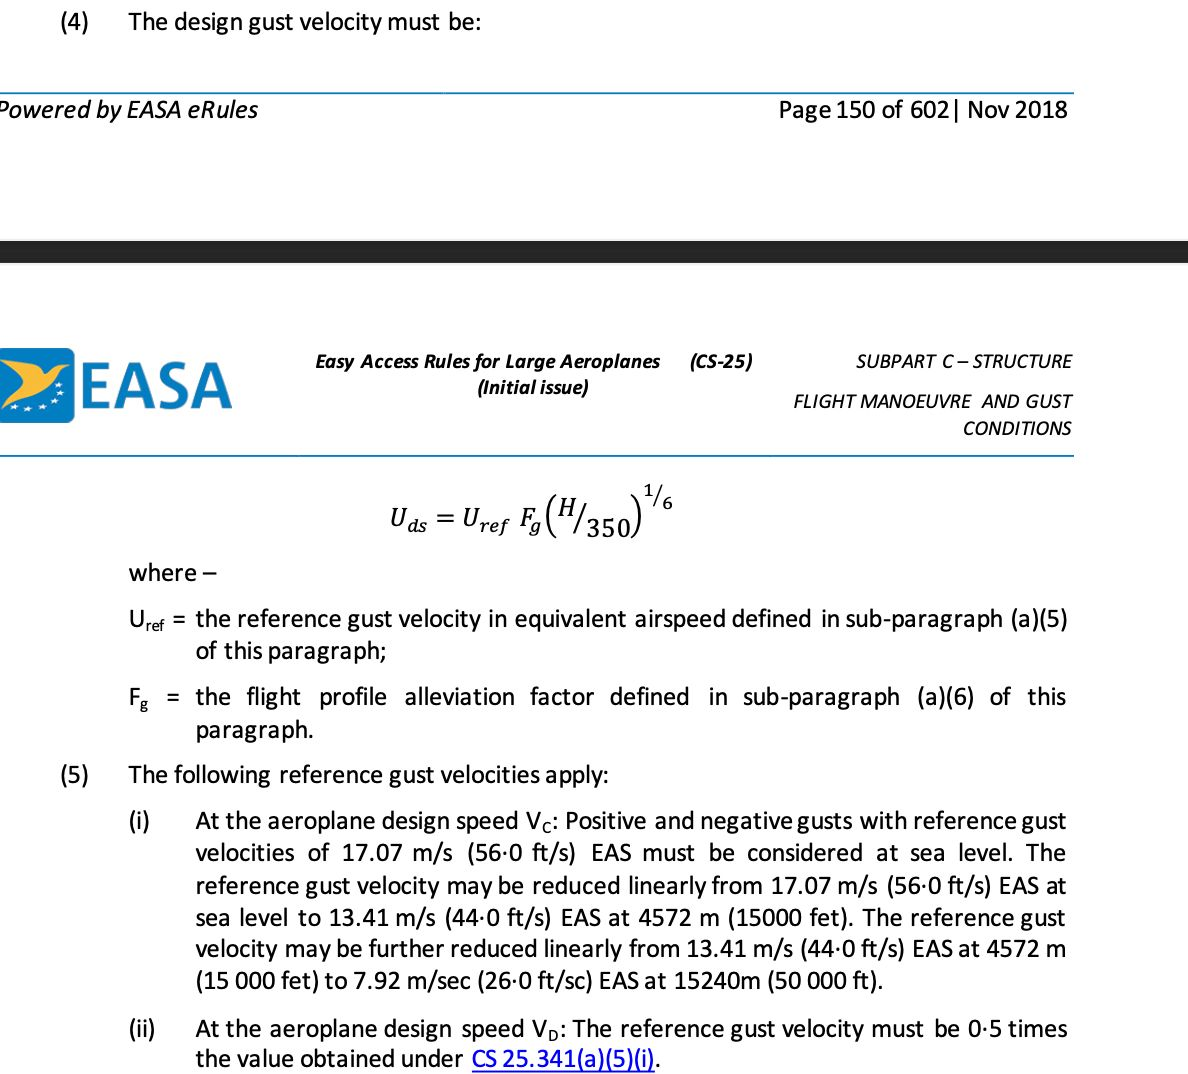

figure(1)
clf;
xline(VD, 'b-', 'LineWidth', 2)
hold on
xline(VC,'--')
hold on
plot(Vspace,n_upperline, 'b-', 'LineWidth', 2)
hold on
plot(Vspace,n_upperline_L, 'b--', 'LineWidth', 2)
hold on
plot(Vspace,n_lowerline, 'b-', 'LineWidth', 2)
hold on
yline(0,'LineWidth',2)
hold on
yline(nmax, 'b-', 'LineWidth', 2)
hold on
plot(Vspace, n4, 'b-', 'LineWidth', 2)
hold on
xline(VA,'--')
hold on
xline(VS1,'--')
legend()

ylim([-4 4])

xlim([0 VD*1.1])
xlabel("VEAS (m/s)")
ylabel("n")

